# Práctica 7: Filtros en frecuencia

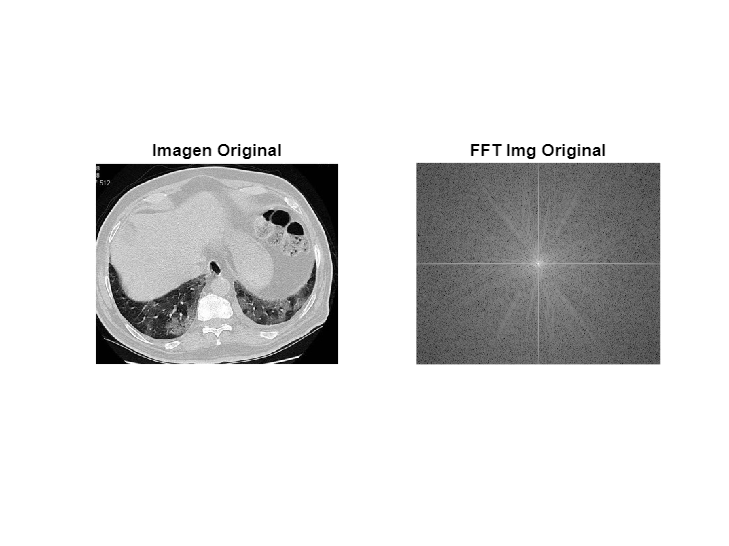

%Cargar imagen 
img = imread("tac_imagen.jpg");
img_gray = rgb2gray(img);

%Aplicar Trans Fourier
f = fft2(img_gray);
f_shifted = fftshift(f);
abs_f_shifted = log(abs(f_shifted)+1);

figure;
subplot(1,2,1), imshow(img_gray), title('Imagen Original');
subplot(1,2,2), imshow(abs_f_shifted, []), title('FFT Img Original');


%Definir los parámetros del filtro
[alto, ancho] = size(f_shifted);
cx = round(ancho/2);
cy = round(alto/2);

r_filtro = 40;

#### Filtro pasa bajas

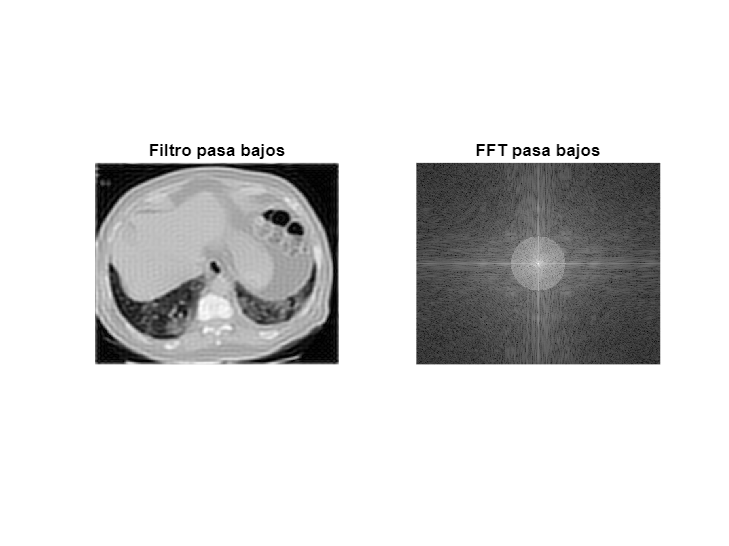

pasa_bajo = zeros(alto, ancho);
for i = 1:alto
    for j = 1:ancho
        r = sqrt((i - cy)^2 + (j - cx)^2);
        if r <= r_filtro
            pasa_bajo(i, j) = 1;
        end
    end
end

%Aplicar filtro a fft
f_low = f_shifted .* pasa_bajo;

% Transformada inversa para obtener la imagen filtrada
img_low = ifft2(ifftshift(f_low));
img_low = abs(img_low);

%Trans Fourier Img Filtrada
f_shifted_low = fftshift(fft2(img_low));
abs_f_shifted_low = log(abs(f_shifted_low)+1);

figure;
subplot(1,2,1), imshow(img_low, []), title('Filtro pasa bajos');
subplot(1,2,2), imshow(abs_f_shifted_low, []), title('FFT pasa bajos');

#### Filtro pasa altos

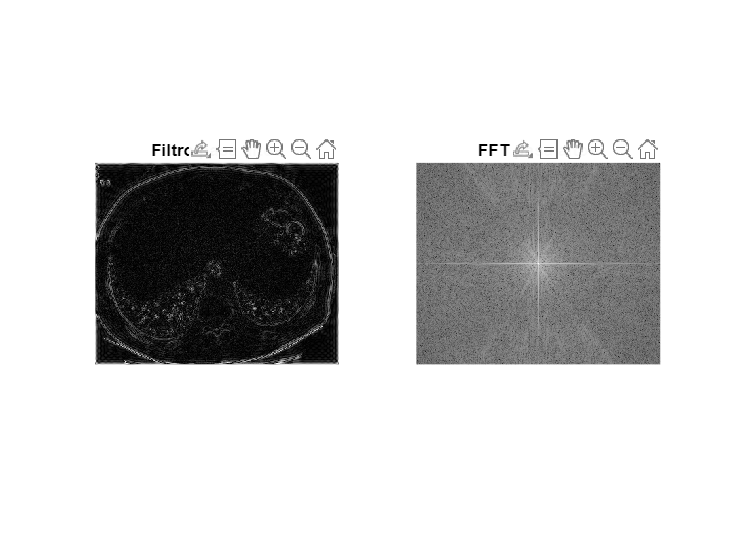

pasa_alto = ones(alto, ancho);
for i = 1:alto
    for j = 1:ancho
        r = sqrt((i - cy)^2 + (j - cx)^2);
        if r <= r_filtro
            pasa_alto(i, j) = 0;
        end
    end
end

%Aplicar filtro a fft
f_high = f_shifted .* pasa_alto;

% Trans inversa para obtener la imagen filtrada
img_high = ifft2(ifftshift(f_high));
img_high = abs(img_high);

%Trans Fourier Img Filtrada
f_shifted_high = fftshift(fft2(img_high));
abs_f_shifted_high = log(abs(f_shifted_high)+1);

figure;
subplot(1,2,1), imshow(img_high, []), title('Filtro pasa altos');
subplot(1,2,2), imshow(abs_f_shifted_high, []), title('FFT pasa altos');